tic;
A = load('stiffness_matrix_1d.mat').A;
f = load('load_vector_1d.mat').fh;
uh_small = load('uh_small.mat').uh;
toc

Elapsed time is 0.050861 seconds.


tic;
uh_d = A\f;
toc

Elapsed time is 0.003427 seconds.


## MG preconditioned CG

## Hermite-cubic interpolation

Nel = (length(A)-2)/4;
h=2/Nel;
dof = 2*(Nel-1);
Ncoefs = 4;
I = eye(dof);
Imat = zeros(2*(dof+1),dof);
for i=1:dof/2
    bl = 2*i;
    Imat(2*bl-1,bl-1) = 1;
    Imat(2*bl,bl) = 1;
end
Imat;

cfmat = coeffmat(h);
for i=1:Nel
    indi = 4*i-3;
    indj = 2*i-1;
    if i==1
        Imat(indi:indi+1,indj:indj+Ncoefs-3) = cfmat(:,3:4);
    elseif i==Nel
        Imat(indi:indi+1,indj-2:indj+Ncoefs-5) = cfmat(:,1:2);
    else
        Imat(indi:indi+1,indj-2:indj+Ncoefs-3) = cfmat;
    end
end
Imat;
y2h = uh_small;
yh = zeros(2*(dof+1)+4,1);
yh(3:end-2) = Imat*y2h(3:end-2);

## CG

% CG routine
fnorm = norm(f);
tol = 1e-10; maxit = length(A);

u0 = yh;
tic;
[uh_cg,num_iter,r_norm] = cg(A,f,u0,tol,maxit);
toc

Elapsed time is 0.007644 seconds.


num_iter

num_iter = 130

r_norm

r_norm = 4.1972e-05

norm(uh_d - uh_cg)

ans = 1.2954e-09

## Weighted Jacobi iteration

ns = [length(A)];
w = 2/3; w2 = 4/3; niter=4;
errs1 = ji(A,f,w,w2,rand(ns(1),1),niter);

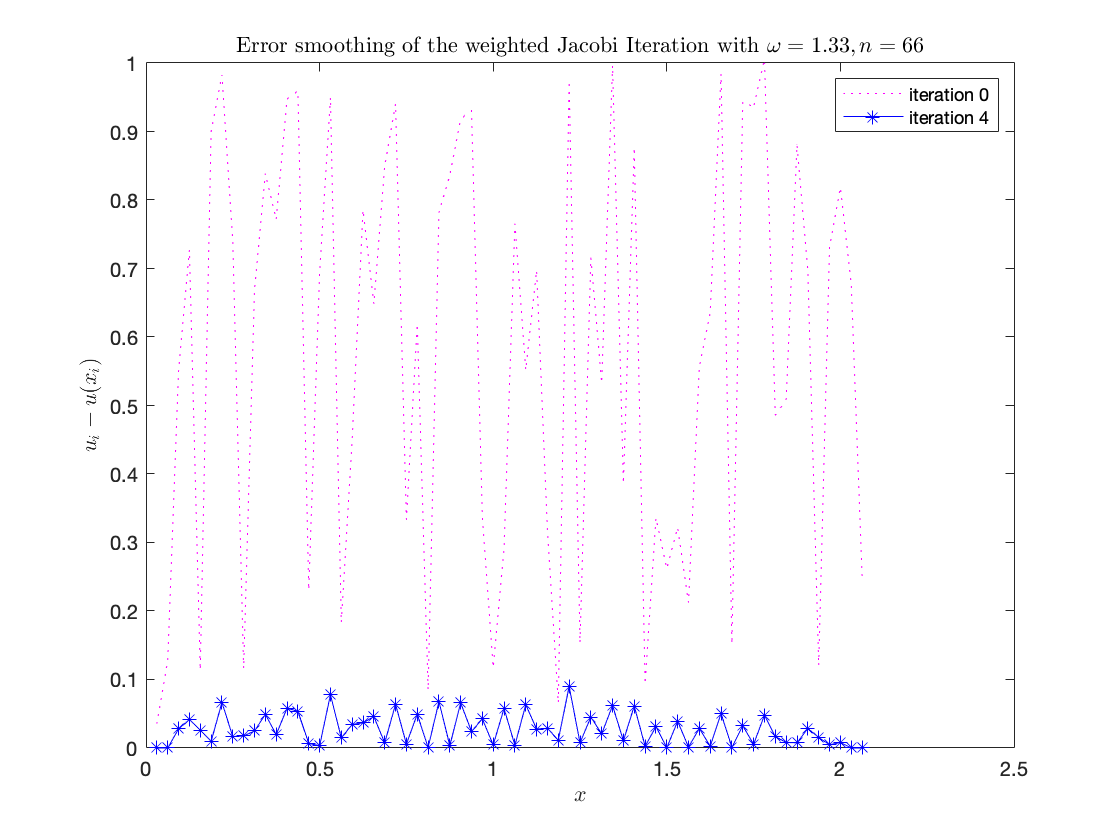

clf
params = ["m:","k-o", "r--", "g--", "b-*"];
for j=1:length(ns)
    figure
    plot(hs(j)*(1:ns(j)),abs(errs1(1,:)),params(1),'DisplayName', sprintf('iteration %i', 0))
    hold on
    plot(hs(j)*(1:ns(j)),abs(errs1(end,:)),params(end),'DisplayName', sprintf('iteration %i', niter))
    title(sprintf('Error smoothing of the weighted Jacobi Iteration with $\\omega = %.2f, n=%i$',w2,ns(j)),'Interpreter',"latex")
    ylim([0 1])
    xlabel('$x$',"Interpreter","latex")
    ylabel('$u_i - u(x_i)$',"Interpreter","latex")
    legend
    
    hold off
end

## Appendix

function errs = ji(A,f,w,w2,u0,niter)
    u_true = A\f;
    % preconditioner
    P = diag(diag(A))/w;
    
    % iteration
    u = u0;
    errs = zeros(niter+1,length(f));
    errs(1,:) = u-u_true;
    for i=1:niter
        u = (1-w2)*u + w2*P\((P-A)*u+f);
        errs(i+1,:) = u-u_true;
    end
end

function errs = sor(A,f,w,u0,niter)
    u_true = A\f;
    L = tril(A,0);
    u = u0;
    errs(1,:) = u-u_true;
    for i=1:niter
        u = (1-w)*u + w*L\((L-A)*u+f);
        errs(i+1,:) = u-u_true;
    end
end

function [x,num_iter,r_norm] = cg(A,b,u0,tol,maxit)
    % _o - for old, _n - for new
    x_o = u0;
    r_o = b - A*x_o;
    p_o = r_o;
    for k=1:maxit
        alpha = (r_o'*r_o)/(p_o'*A*p_o);
        x_n = x_o + alpha*p_o;
        r_n = r_o - alpha*(A*p_o);
        if norm(r_n) < tol
            x = x_n;
            num_iter = k;
            r_norm = norm(r_n);
            return
        else
            beta = (r_n'*r_n)/(r_o'*r_o);
            p_n = r_n + beta*p_o;
        end
        % for the next iteration
        x_o = x_n;
        r_o = r_n;
        p_o = p_n;
    end
    x = x_o;
    num_iter = maxit;
    r_norm = norm(r_o);
end

function coeffs = coeffmat(h)
    coeffs = [1/2 h/8 1/2 -h/8; 
        -3/(2*h) -1/(4) 3/(2*h) -1/(4)];
end